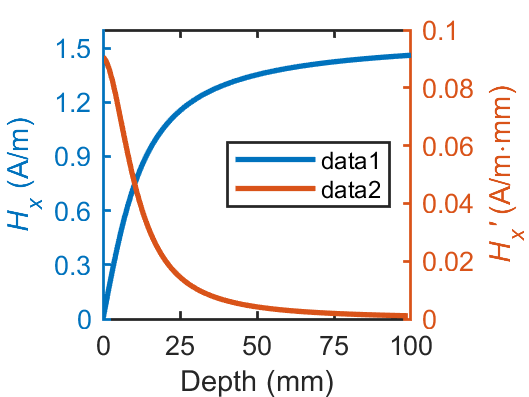

clc;clear;
% syms x  h b y;
% pretty(Hx(x,y,b,h));
% Hx(x,y,b,h)
% 缺陷半宽0.1，深1，提离1毫米，
x=0;   %空间位置
y=1; %提离值
b=0.1; %缺陷半宽
% h=1;   %缺陷深度


% 创建 figure
fig = figure;
% 创建 axes
ax = axes(fig);
% 创建 legend(ax)
leg=legend(ax);

% 设置坐标标签
x_label="Depth (mm)";
y_label1="\it{H_x} \rm(A/m)";
y_label2="\itH_x' \rm(A/m\cdotmm)";

% 构建函数
h=linspace(0,100);
y1=Hx(x,y,b,h);
yyaxis left;
h1=plot(h,y1);
yyaxis right;
h2=plot(h(1:end-1),diff(y1));

plot_fig(fig, ax, leg, x_label, y_label1, y_label2, h1, h2);

function plot_fig(fig, ax, leg, x_label, y_label1, y_label2, h1, h2)

fig.Units = 'centimeters';
fig.Position(3:4) = [7, 5.25]; % 7cmx5.25cm
fig.Color = [1.0, 1.0, 1.0]; % background color

ax.Units = 'centimeters';
% ax.Position = [1.4, 1, 4, 4];
ax.LineWidth = 1;
ax.FontName ='Arial'; % 'Times New Roman';
ax.FontSize = 10;
% ax.TickLabelInterpreter = 'latex';

ax.XLabel.String = x_label;
ax.XLabel.Units = 'normalized';
%ax.XLabel.Position = [0.5, -0.125];
% ax.XLabel.Interpreter = 'latex';
% ax.XLim(1) = 0;
ax.XTick=(0:25:100);
% tick
ax.XMinorTick = 'off';
ax.TickDir = 'in';

ax.TickLength(1) = 0.02;

yyaxis left;

set(h1,'LineStyle','-','linewidth',2);
ax.YLabel.String=y_label1;
ax.YLabel.Units = 'normalized';
% ax.YLabel.Position = [-0.1, 0.5];
% ax.YLabel.Interpreter = 'latex';
% ax.YLim(1) = 0;
axis([0 100 0 1.6]);
ax.YTick=(0:0.3:1.5);
ax.YMinorTick = 'off';
ax.TickLength = [0.02 0.035];
ax.TickDir = 'in';

yyaxis right;

set(h2,'LineStyle','-','linewidth',2);
ax.YLabel.String=y_label2;
% ax.YLabel.Position = [0, 0.5];
% ax.YLabel.Interpreter = 'latex';
% ax.YLim(1) = 0;
axis([0 100 0 0.1]);
ax.YTick=(0:0.02:0.1);
ax.YMinorTick = 'off';
ax.TickDir = 'in';


leg.Interpreter = 'tex';
leg.Location = 'east';
leg.Box = 'on';

end


